clear
load 5_jumps
lat=Position.latitude;
lon=Position.longitude;
alt = Position.altitude;
positionDatetime=Position.Timestamp;

Xacc = Acceleration.X;
Yacc = Acceleration.Y;
Zacc = Acceleration.Z;
accelDatetime=Acceleration.Timestamp;

% We use the following to obtain linear time data in seconds from a datetime array
positionTime=timeElapsed(positionDatetime);
accelTime=timeElapsed(accelDatetime);

Plotting lat and long

classificationLearner

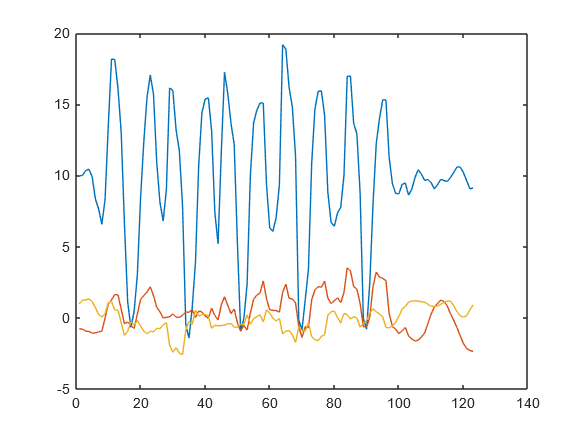

windowSize = 5; 
t = linspace(0,100,217);
b = (1/windowSize)*ones(1,windowSize);
a = 1;
A = filter(b,a,lat);
nlat = A(windowSize:end);
A = filter(b,a,lon);
nlon = A(windowSize:end);
A = filter(b,a,Zacc);
nZa = A(windowSize:end);

A = filter(b,a,Xacc);
nXa = A(windowSize:end);

A = filter(b,a,Yacc);
nYa = A(windowSize:end);

% nlat(1) = 42.2992;
% nlat(2) = 42.2992;
% nlat(3) = 42.2992;
% nlat(4) = 42.2992;
% nlat(5) = 42.2992;



% plot(lat,lon);
% hold on;


plot(nZa);
hold on;
plot(nXa);
plot(nYa);
hold off



% plot(nlat,nlon);
% set(gca,'XColor', 'none','YColor','none');
% set(gca, 'color', 'none');
% f = gcf;
% exportgraphics(f,'shape.png','Resolution',300)


### 3. Coding The Model

In this example, latitude and longitude have been stored into variable names *lat* and *lon* respectively. The first step in using these to calculate distance is to declare a couple of variables: one will represent the circumference of the earth in miles, the other will represent the total distance traveled, which will be set to zero for now.

earthCirc = 24901;
totaldis = 0;

To solve this problem, calculations will have to be repeated several times in a loop. Because of this, we use a function called a [`for loop`](https://www.mathworks.com/help/matlab/ref/for.html) which will repeat a block of code *for* a specified number of times. In this case, we want to have it run until the end of our vector of data. The [`length`](https://www.mathworks.com/help/matlab/ref/length.html) command can be used to determine the number of elements in a vector and therefore how many times we need to run the loop. When solving for the difference in position, one position and the next position are used at the same time, so we need to stop one before the end of the vector as seen below. If this isn't done, we will get an error because we will be trying to acces data from outside of the vector.

for i = 1:(length(lat)-1)

Now we save the first position and the second position into variables. We will do this using the variable *i* from above. This variable is a vector from 1 to the end of our latitude vector which can be used to index the latitude and longitude vectors.

    lat1 = lat(i);     % The first latitude
    lat2 = lat(i+1);   % The second latitude
    lon1 = lon(i);     % The first longitude
    lon2 = lon(i+1);   % The second longitude

Thankfully for us, MATLAB has a command [`distance`](https://www.mathworks.com/help/map/ref/distance.html) that calculates distance when given latitude and longitude. This will give us the difference in degrees which we will then turn into length by creating equivalent fractions:


$$\frac{\textrm{traveledDistance}}{\textrm{earth'sCircumference}}=\frac{\textrm{degreesTraveled}}{\textrm{earth'sDegrees}}\;$$


From this we solve for 'traveledDistance'. We will use 360 for 'earth’sDegrees' because that is the total number of degrees in a circle. While the earth is not a perfect circle, this will still be a good estimation

    degDis = distance(lat1, lon1, lat2, lon2);

The total distance traveled is: 0.4093 miles


    dis = (degDis/360)*earthCirc;

You took 864.4514 steps


Now we add up the distance and store it into the *totaldis* variable. What this code will do is take the previous total distance and add the distance just calculated onto it. With this, we have calculated everything that we needed to within the for loop and must close the loop by using the [`end`](https://www.mathworks.com/help/matlab/ref/end.html) command.

    totaldis = totaldis + dis;
end

Once the for loop has finished, we will have the total distance traveled! From here, we need to divide the total distance traveled by the stride to get the steps taken. For this example, we will use the average stride of 2.5ft. Since *totaldis* is the total distance traveled in miles, we will have to convert this into feet before we can divide it by the stride. 

stride = 2.5;                   % Average stride (ft)
totaldis_ft = totaldis*5280;    % Converting distance from miles to feet
steps = totaldis_ft/stride;

An easy way to see the data that you are interested in is by priniting it to the screen once you find it. While you could also show it by removing the semicolon, the [`disp`](https://www.mathworks.com/help/matlab/ref/disp.html) command allows you to add text as well to specify exactly what data you are looking at.

disp(['The total distance traveled is: ', num2str(totaldis),' miles'])
disp(['You took ', num2str(steps) ' steps'])